%% COMPLETE LSTM VOWEL A CLASSIFIER 
clc; clear; close all;

rng(42, 'twister');
fprintf('Random seed set to 42\n\n');

Random seed set to 42



%% CONFIGURATION
FREQ_MIN = 0.1;
FREQ_MAX = 450;
SAMPLE_RATE = 12500;

%%LOAD DATA
fprintf('=== Loading Data ===\n');

=== Loading Data ===


tic;

trainData = load('trainv2.mat');
FinalTableTrain = trainData.FinalTable;
clear trainData

testData = load('testv2.mat');
FinalTableTest = testData.FinalTable;
clear testData

fprintf(' Loaded in %.1f sec\n', toc);

 Loaded in 607.8 sec


fprintf('  Train: %d rows\n', height(FinalTableTrain));

  Train: 701 rows


fprintf('  Test: %d rows\n\n', height(FinalTableTest));

  Test: 253 rows



%% PROCESS LABELS
fprintf('=== Processing Labels ===\n');

=== Processing Labels ===



% Normalize training labels
v = upper(strtrim(FinalTableTrain.Vowels));
v(v == "" | v == "N" | v == "NONE") = "";
FinalTableTrain.Vowels = v;

% Normalize test labels
v_test = upper(strtrim(FinalTableTest.Vowels));
v_test(v_test == "" | v_test == "N" | v_test == "NONE") = "";
FinalTableTest.Vowels = v_test;

% Add multi-hot encoding
FinalTableTrain = addVowelsMultiHot(FinalTableTrain);

Multi-hot encoding added:
  isA: 215 samples
  isE: 274 samples
  isI: 86 samples
  isO: 283 samples
  isU: 86 samples


FinalTableTest = addVowelsMultiHot(FinalTableTest);

Multi-hot encoding added:
  isA: 45 samples
  isE: 183 samples
  isI: 60 samples
  isO: 51 samples
  isU: 25 samples



% Extract Vowel A labels 
Ytrain_A = double(FinalTableTrain.isA);  
Ytest_A = double(FinalTableTest.isA);   

fprintf('Training distribution:\n');

Training distribution:


fprintf('  Present (1): %d (%.1f%%)\n', sum(Ytrain_A==1), 100*sum(Ytrain_A==1)/length(Ytrain_A));

  Present (1): 215 (30.7%)


fprintf('  Absent (0):  %d (%.1f%%)\n', sum(Ytrain_A==0), 100*sum(Ytrain_A==0)/length(Ytrain_A));

  Absent (0):  486 (69.3%)



fprintf('\nTest distribution:\n');


Test distribution:


fprintf('  Present (1): %d (%.1f%%)\n', sum(Ytest_A==1), 100*sum(Ytest_A==1)/length(Ytest_A));

  Present (1): 45 (17.8%)


fprintf('  Absent (0):  %d (%.1f%%)\n\n', sum(Ytest_A==0), 100*sum(Ytest_A==0)/length(Ytest_A));

  Absent (0):  208 (82.2%)



%% EXTRACT TRAINING FEATURES
fprintf('=== Extracting Training Features ===\n');

=== Extracting Training Features ===


fprintf('This will take several minutes...\n\n');

This will take several minutes...




N = height(FinalTableTrain);
Xtrain_cell = cell(N, 1);

tic;
for i = 1:N
    Xtrain_cell{i} = extractLSTMFeatures(FinalTableTrain, i, FREQ_MIN, FREQ_MAX, SAMPLE_RATE);
    
    if mod(i, 100) == 0 || i == N
        elapsed = toc;
        pct = 100 * i / N;
        eta = elapsed * (N - i) / i;
        
        fprintf('  [%6d/%6d] %.1f%% | Elapsed: %.1fm | ETA: %.1fm\n', ...
            i, N, pct, elapsed/60, eta/60);
    end
end

  [   100/   701] 14.3% | Elapsed: 0.1m | ETA: 0.4m
  [   200/   701] 28.5% | Elapsed: 0.1m | ETA: 0.2m
  [   300/   701] 42.8% | Elapsed: 0.1m | ETA: 0.2m
  [   400/   701] 57.1% | Elapsed: 0.1m | ETA: 0.1m
  [   500/   701] 71.3% | Elapsed: 0.2m | ETA: 0.1m
  [   600/   701] 85.6% | Elapsed: 0.2m | ETA: 0.0m
  [   700/   701] 99.9% | Elapsed: 0.2m | ETA: 0.0m
  [   701/   701] 100.0% | Elapsed: 0.2m | ETA: 0.0m



totalTime = toc;
fprintf('\n Training features ready (%.1f min)\n', totalTime/60);


 Training features ready (0.2 min)



[numFeatures, seqLength] = size(Xtrain_cell{1});
fprintf('  Feature shape: %d features × %d timesteps\n\n', numFeatures, seqLength);

  Feature shape: 900 features × 39 timesteps




clear FinalTableTrain

%% EXTRACT TEST FEATURES
fprintf('=== Extracting Test Features ===\n');

=== Extracting Test Features ===



M = height(FinalTableTest);
Xtest_cell = cell(M, 1);

tic;
for i = 1:M
    Xtest_cell{i} = extractLSTMFeatures(FinalTableTest, i, FREQ_MIN, FREQ_MAX, SAMPLE_RATE);
    
    if mod(i, 50) == 0 || i == M
        elapsed = toc;
        pct = 100 * i / M;
        eta = elapsed * (M - i) / i;
        
        fprintf('  [%4d/%4d] %.1f%% | ETA: %.1fm\n', i, M, pct, eta/60);
    end
end

  [  50/ 253] 19.8% | ETA: 0.0m
  [ 100/ 253] 39.5% | ETA: 0.0m
  [ 150/ 253] 59.3% | ETA: 0.0m
  [ 200/ 253] 79.1% | ETA: 0.0m
  [ 250/ 253] 98.8% | ETA: 0.0m
  [ 253/ 253] 100.0% | ETA: 0.0m



fprintf('\n Test features ready (%.1f min)\n\n', toc/60);


 Test features ready (0.0 min)




clear FinalTableTest

%% TRAIN/VALIDATION SPLIT
fprintf('=== Creating Train/Val Split ===\n');

=== Creating Train/Val Split ===



valRatio = 0.2;
numSamples = length(Ytrain_A);
shuffleIdx = randperm(numSamples);
valCount = round(numSamples * valRatio);

trainIdx = shuffleIdx(valCount+1:end);
valIdx = shuffleIdx(1:valCount);
% Calculate the split point (No shuffling)
%trainCount = floor(numSamples * (1 - valRatio));

% Define indices chronologically
%trainIdx = 1:trainCount;                  % First 80% (0 to T)
%valIdx   = (trainCount + 1):numSamples;   % Last 20%  (T to End)

% Split data - keep as numeric 0/1
Xtrain = Xtrain_cell(trainIdx);
Ytrain = Ytrain_A(trainIdx);

Xval = Xtrain_cell(valIdx);
Yval = Ytrain_A(valIdx);

fprintf('Split completed:\n');

Split completed:


fprintf('  Training:   %d samples (%.0f%%)\n', length(trainIdx), (1-valRatio)*100);

  Training:   561 samples (80%)


fprintf('  Validation: %d samples (%.0f%%)\n\n', length(valIdx ), valRatio*100);

  Validation: 140 samples (20%)




original_counts = [sum(Ytrain==0), sum(Ytrain==1)];
fprintf('Training set distribution (before augmentation):\n');

Training set distribution (before augmentation):


fprintf('  Absent (0):  %d\n', original_counts(1));

  Absent (0):  389


fprintf('  Present (1): %d\n\n', original_counts(2));

  Present (1): 172



%%  DATA AUGMENTATION
fprintf('=== Augmenting Training Data ===\n');

=== Augmenting Training Data ===



idx0 = find(Ytrain == 0);  % Absent
idx1 = find(Ytrain == 1);  % Present

fprintf('Current distribution:\n');

Current distribution:


fprintf('  Absent (0):  %d\n', length(idx0));

  Absent (0):  389


fprintf('  Present (1): %d\n', length(idx1));

  Present (1): 172



if length(idx0) < length(idx1)
    minority_idx = idx0;
    minority_label = 0;
    majority_idx = idx1;
    fprintf('   Minority class: Absent (0)\n');
else
    minority_idx = idx1;
    minority_label = 1;
    majority_idx = idx0;
    fprintf('   Minority class: Present (1)\n');
end

   Minority class: Present (1)


targetN = length(majority_idx);
numToGenerate = targetN - length(minority_idx);

fprintf('\nGenerating %d augmented samples...\n', numToGenerate);


Generating 217 augmented samples...



noise_std = 0.05;
augmented_features = cell(numToGenerate, 1);
augmented_labels = zeros(numToGenerate, 1);  % Numeric 0/1

tic;
for i = 1:numToGenerate
    source_idx = minority_idx(randi(length(minority_idx)));
    original = Xtrain{source_idx};
    
    noise = noise_std * randn(size(original), 'single');
    augmented_features{i} = original + noise;
    augmented_labels(i) = minority_label;
    
    if mod(i, 100) == 0 || i == numToGenerate
        fprintf('  Generated: %d/%d\n', i, numToGenerate);
    end
end

  Generated: 100/217
  Generated: 200/217
  Generated: 217/217



fprintf(' Augmentation done (%.1f sec)\n\n', toc);

 Augmentation done (0.4 sec)



% Combine original + augmented
XtrainFinal = [Xtrain; augmented_features];
YtrainFinal_numeric = [Ytrain; augmented_labels];

% NOW convert to categorical with EXPLICIT ordering
YtrainFinal = categorical(YtrainFinal_numeric, [0, 1], {'Absent', 'Present'});
Yval_cat = categorical(Yval, [0, 1], {'Absent', 'Present'});

balanced_counts = [sum(YtrainFinal_numeric==0), sum(YtrainFinal_numeric==1)];
fprintf('Balanced training set:\n');

Balanced training set:


fprintf('  Absent (0):  %d (%.1f%%)\n', balanced_counts(1), 100*balanced_counts(1)/sum(balanced_counts));

  Absent (0):  389 (50.0%)


fprintf('  Present (1): %d (%.1f%%)\n\n', balanced_counts(2), 100*balanced_counts(2)/sum(balanced_counts));

  Present (1): 389 (50.0%)




clear Xtrain augmented_features Xtrain_cell

%% DATA NORMALIZATION (Standard Scaler)
fprintf('=== Normalizing Features (Standard Scaler) ===\n');

=== Normalizing Features (Standard Scaler) ===



% 1. Concatenate all training samples to calculate global stats
allTrainData = horzcat(XtrainFinal{:}); 

mu = mean(allTrainData, 2);
sigma = (std(allTrainData, 0, 2)+eps);


fprintf('  Calculated stats for %d features\n', length(mu));

  Calculated stats for 900 features



%  Apply normalization to Training Set
for i = 1:length(XtrainFinal)
    XtrainFinal{i} = (XtrainFinal{i} - mu) ./ sigma;
end

%  Apply SAME normalization to Validation Set (using train mu/sigma)
for i = 1:length(Xval)
    Xval{i} = (Xval{i} - mu) ./ sigma;
end

%  Apply SAME normalization to Test Set (using train mu/sigma)
for i = 1:length(Xtest_cell)
    Xtest_cell{i} = (Xtest_cell{i} - mu) ./ sigma;
end

fprintf('  Normalization complete.\n\n');

  Normalization complete.




clear allTrainData % Free up memory

%% BUILD LSTM MODEL
fprintf('=== Building LSTM Architecture ===\n');

=== Building LSTM Architecture ===



layers = [
    sequenceInputLayer(numFeatures, 'Name', 'input')
    
    bilstmLayer(64, 'OutputMode', 'last', 'Name', 'bilstm1')
    batchNormalizationLayer('Name', 'bn1')
    dropoutLayer(0.5, 'Name', 'dropout1')
    
    %bilstmLayer(20, 'OutputMode', 'last', 'Name', 'bilstm2')
    %batchNormalizationLayer('Name', 'bn2')
    %dropoutLayer(0.3, 'Name', 'dropout2')
    
    %fullyConnectedLayer(16, 'Name', 'fc1')
    %leakyReluLayer(0.2, 'Name', 'leaky_relu1')
    %dropoutLayer(0.4, 'Name', 'dropout3')
    
    fullyConnectedLayer(2, 'Name', 'fc_out')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'output')
];


%% TRAINING CONFIGURATION
fprintf('=== Training Configuration ===\n');

=== Training Configuration ===


%'L2Regularization', 0.01, ...
options = trainingOptions('adam', ...
    'InitialLearnRate', 1e-4, ...
    'MaxEpochs', 30, ...
    'MiniBatchSize', 8, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {Xval, Yval_cat}, ...
    'ValidationFrequency', 20, ...
    'ValidationPatience', 15, ...
    'ExecutionEnvironment', 'auto', ...
    'Plots', 'training-progress', ...
    'Verbose', true, ...
    'VerboseFrequency', 10, ...
    'GradientThreshold', 1, ...
    'SequenceLength', 'longest', ...
    'SequencePaddingDirection', 'right');

fprintf('Settings:\n');

Settings:


fprintf('  Optimizer: Adam\n');

  Optimizer: Adam


fprintf('  Learning rate: %.0e\n', options.InitialLearnRate);

  Learning rate: 1e-04


fprintf('  Epochs: %d\n', options.MaxEpochs);

  Epochs: 30


fprintf('  Batch size: %d\n', options.MiniBatchSize);

  Batch size: 8


fprintf('  Validation check: every %d iterations\n', options.ValidationFrequency);

  Validation check: every 20 iterations


fprintf('  Early stopping patience: %d checks\n\n', options.ValidationPatience);

  Early stopping patience: 15 checks



Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:13 |       50.00% |       50.71% |       1.5021 |       0.9923 |      1.0000e-04 |
|       1 |          10 |       00:00:19 |       75.00% |              |       0.8473 |              |      1.0000e-04 |
|       1 |          20 |       00:00:23 |       50.00% |       60.71% |       1.2006 |       0.8251 |      1.0000e-04 |
|       1 |          30 |       00:00:26 |       50.00% |              |       0.9467 |              |      1.0000e-04 |
|       

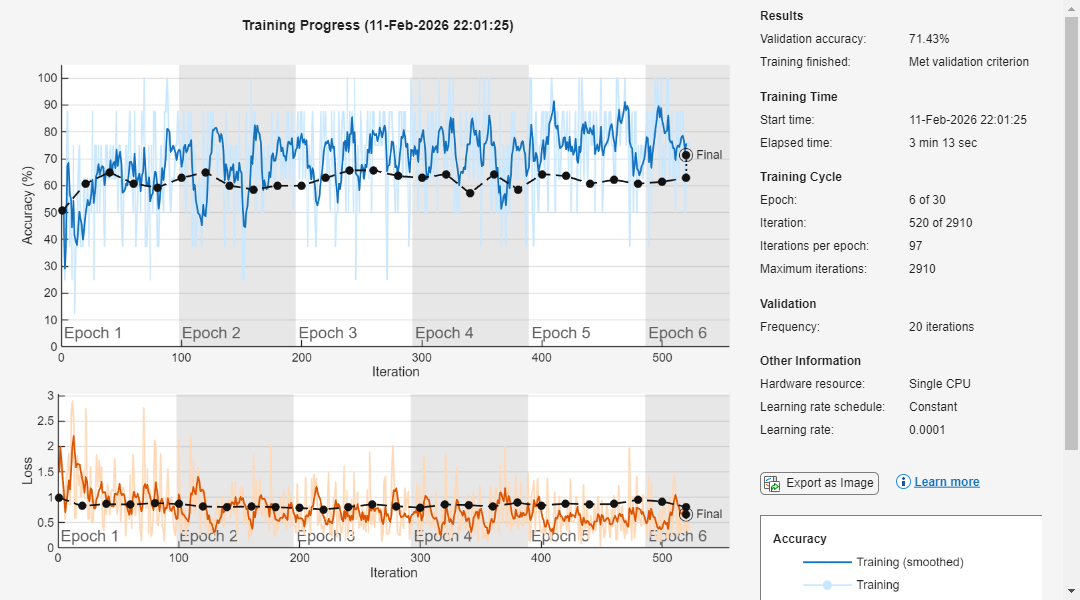

%% TRAIN MODEL
tic;
net_A = trainNetwork(XtrainFinal, YtrainFinal, layers, options);

trainTime = toc;

fprintf('\n');
fprintf(' Time: %.1f minutes \n', trainTime/60);

 Time: 4.1 minutes 


%% EVALUATE TRAINING SET
fprintf('=== Evaluating Training Set ===\n');

=== Evaluating Training Set ===



YPred_train = classify(net_A, XtrainFinal);

Ytrue_train_num = double(YtrainFinal == "Present");
YPred_train_num = double(YPred_train == "Present");

TP_train = sum((YPred_train_num == 1) & (Ytrue_train_num == 1));
FP_train = sum((YPred_train_num == 1) & (Ytrue_train_num == 0));
FN_train = sum((YPred_train_num == 0) & (Ytrue_train_num == 1));
TN_train = sum((YPred_train_num == 0) & (Ytrue_train_num == 0));

acc_train = sum(YPred_train_num == Ytrue_train_num) / length(Ytrue_train_num);
prec_train = TP_train / (TP_train + FP_train + eps);
rec_train = TP_train / (TP_train + FN_train + eps);
F1_train = 2 * prec_train * rec_train / (prec_train + rec_train + eps);

fprintf('Results:\n');

Results:


fprintf('  Accuracy:  %.2f%%\n', acc_train*100);

  Accuracy:  87.40%


fprintf('  Precision: %.2f%%\n', prec_train*100);

  Precision: 94.50%


fprintf('  Recall:    %.2f%%\n', rec_train*100);

  Recall:    79.43%


fprintf('  F1-Score:  %.2f%%\n', F1_train*100);

  F1-Score:  86.31%


fprintf('\nConfusion Matrix:\n');


Confusion Matrix:


fprintf('  TN=%d  FP=%d\n', TN_train, FP_train);

  TN=371  FP=18


fprintf('  FN=%d  TP=%d\n\n', FN_train, TP_train);

  FN=80  TP=309



%% EVALUATE VALIDATION SET
fprintf('=== Evaluating Validation Set ===\n');

=== Evaluating Validation Set ===



YPred_val = classify(net_A, Xval);

Ytrue_val_num  = double(Yval_cat == "Present");
YPred_val_num = double(YPred_val  == "Present");


TP_val = sum((YPred_val_num == 1) & (Ytrue_val_num == 1));
FP_val = sum((YPred_val_num == 1) & (Ytrue_val_num == 0));
FN_val = sum((YPred_val_num == 0) & (Ytrue_val_num == 1));
TN_val = sum((YPred_val_num == 0) & (Ytrue_val_num == 0));

acc_val = sum(YPred_val_num == Ytrue_val_num) / length(Ytrue_val_num);
prec_val = TP_val / (TP_val + FP_val + eps);
rec_val = TP_val / (TP_val + FN_val + eps);
F1_val = 2 * prec_val * rec_val / (prec_val + rec_val + eps);

fprintf('Results:\n');

Results:


fprintf('  Accuracy:  %.2f%%\n', acc_val*100);

  Accuracy:  71.43%


fprintf('  Precision: %.2f%%\n', prec_val*100);

  Precision: 53.85%


fprintf('  Recall:    %.2f%%\n', rec_val*100);

  Recall:    48.84%


fprintf('  F1-Score:  %.2f%%\n', F1_val*100);

  F1-Score:  51.22%


fprintf('\nConfusion Matrix:\n');


Confusion Matrix:


fprintf('  TN=%d  FP=%d\n', TN_val, FP_val);

  TN=79  FP=18


fprintf('  FN=%d  TP=%d\n\n', FN_val, TP_val);

  FN=22  TP=21




%% EVALUATE TEST SET 
fprintf('=== Evaluating Test Set ===\n');

=== Evaluating Test Set ===



Ytest_cat = categorical(Ytest_A, [0, 1], {'Absent', 'Present'});
YPred_test = classify(net_A, Xtest_cell);

Ytest_num  = double(Ytest_cat == "Present");
YPred_test_num= double(YPred_test  == "Present");


TP = sum((YPred_test_num == 1) & (Ytest_num == 1));
FP = sum((YPred_test_num == 1) & (Ytest_num == 0));
FN = sum((YPred_test_num == 0) & (Ytest_num == 1));
TN = sum((YPred_test_num == 0) & (Ytest_num == 0));

acc_test = sum(YPred_test_num == Ytest_num) / length(Ytest_num);
prec_test = TP / (TP + FP + eps);
rec_test = TP / (TP + FN + eps);
F1_test = 2 * prec_test * rec_test / (prec_test + rec_test + eps);

fprintf('Results:\n');

Results:


fprintf('  Accuracy:  %.2f%%\n', acc_test*100);

  Accuracy:  64.82%


fprintf('  Precision: %.2f%%\n', prec_test*100);

  Precision: 25.00%


fprintf('  Recall:    %.2f%%\n', rec_test*100);

  Recall:    48.89%


fprintf('  F1-Score:  %.2f%%\n', F1_test*100);

  F1-Score:  33.08%


fprintf('\nConfusion Matrix:\n');


Confusion Matrix:


fprintf('  TN=%d  FP=%d\n', TN, FP);

  TN=142  FP=66


fprintf('  FN=%d  TP=%d\n\n', FN, TP);

  FN=23  TP=22



%% BLOCK 14: COMPARATIVE SUMMARY
fprintf('\n');
fprintf('╔═══════════════════════════════════════════════════════════════════╗\n');

╔═══════════════════════════════════════════════════════════════════╗


fprintf('║                   COMPARATIVE SUMMARY                             ║\n');

║                   COMPARATIVE SUMMARY                             ║


fprintf('╠═══════════════════════════════════════════════════════════════════╣\n');

╠═══════════════════════════════════════════════════════════════════╣


fprintf('║  Metric      │   Training  │  Validation │    Test     │  T→T Gap ║\n');

║  Metric      │   Training  │  Validation │    Test     │  T→T Gap ║


fprintf('╠═══════════════════════════════════════════════════════════════════╣\n');

╠═══════════════════════════════════════════════════════════════════╣


fprintf('║  Accuracy    │   %6.2f%%   │   %6.2f%%   │  %6.2f%%   │  %.1f%%    ║\n', ...
    acc_train*100, acc_val*100, acc_test*100, (acc_train-acc_test)*100);

║  Accuracy    │    87.40%   │    71.43%   │   64.82%   │  22.6%    ║


fprintf('║  Precision   │   %6.2f%%   │   %6.2f%%   │  %6.2f%%   │  %.1f%%    ║\n', ...
    prec_train*100, prec_val*100, prec_test*100, (prec_train-prec_test)*100);

║  Precision   │    94.50%   │    53.85%   │   25.00%   │  69.5%    ║


fprintf('║  Recall      │   %6.2f%%   │   %6.2f%%   │  %6.2f%%   │  %.1f%%    ║\n', ...
    rec_train*100, rec_val*100, rec_test*100, (rec_train-rec_test)*100);

║  Recall      │    79.43%   │    48.84%   │   48.89%   │  30.5%    ║


fprintf('║  F1-Score    │   %6.2f%%   │   %6.2f%%   │  %6.2f%%   │  %.1f%%    ║\n', ...
    F1_train*100, F1_val*100, F1_test*100, (F1_train-F1_test)*100);

║  F1-Score    │    86.31%   │    51.22%   │   33.08%   │  53.2%    ║


fprintf('╚═══════════════════════════════════════════════════════════════════╝\n\n');

╚═══════════════════════════════════════════════════════════════════╝



%% BLOCK 15: VISUALIZATIONS
fprintf('=== Creating Visualizations ===\n');

=== Creating Visualizations ===


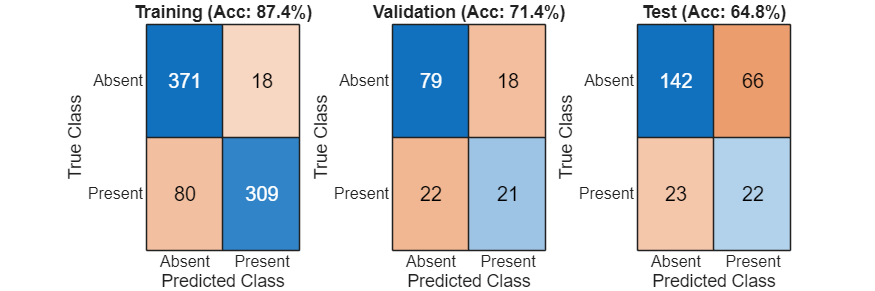


% 1. CONFUSION MATRICES
figure('Position', [50 50 1500 500], 'Name', 'Confusion Matrices');

% Training Matrix
subplot(1,3,1);
cmTrain = confusionchart(YtrainFinal, YPred_train);
title(sprintf('Training (Acc: %.1f%%)', acc_train*100));

% Validation Matrix
subplot(1,3,2);
cmVal = confusionchart(Yval_cat, YPred_val);
title(sprintf('Validation (Acc: %.1f%%)', acc_val*100));

% Test Matrix
% Note: We use the variables created in Block 13
subplot(1,3,3);
cmTest = confusionchart(Ytest_cat, YPred_test);
title(sprintf('Test (Acc: %.1f%%)', acc_test*100));


fprintf(' Confusion matrices created\n');

 Confusion matrices created


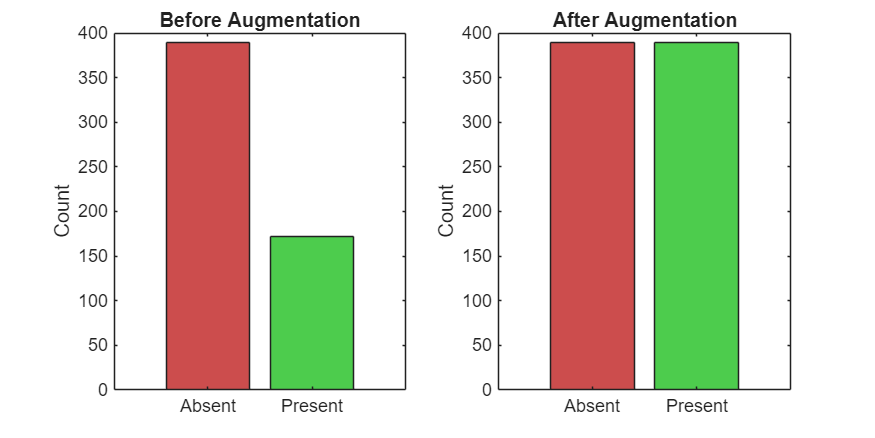


% 2. CLASS DISTRIBUTION
figure('Position', [100 100 1000 500], 'Name', 'Class Distribution');

subplot(1,2,1);
b1 = bar(categorical({'Absent','Present'}), original_counts);
title('Before Augmentation');
ylabel('Count');
b1.FaceColor = 'flat';
b1.CData(1,:) = [0.8 0.3 0.3]; % Red
b1.CData(2,:) = [0.3 0.8 0.3]; % Green

subplot(1,2,2);
b2 = bar(categorical({'Absent','Present'}), balanced_counts);
title('After Augmentation');
ylabel('Count');
b2.FaceColor = 'flat';
b2.CData(1,:) = [0.8 0.3 0.3];
b2.CData(2,:) = [0.3 0.8 0.3];


fprintf(' Distribution charts created\n\n');

 Distribution charts created



%% ROC & AUC CALCULATION AND PLOTTING
fprintf('=== Calculating ROC and AUC ===\n');

=== Calculating ROC and AUC ===



% GET PROBABILITY SCORES
% We need the second column of 'scores' which corresponds to the "Present" class
[~, scores_train] = classify(net_A, XtrainFinal);
[~, scores_val]   = classify(net_A, Xval);
[~, scores_test]  = classify(net_A, Xtest_cell);

% 2. CALCULATE PERFCURVE (ROC COORDINATES)
% The 3rd output '~' is thresholds , 4th output is AUC
[Xroc_train, Yroc_train, ~, AUC_train] = perfcurve(YtrainFinal, scores_train(:,2), 'Present');
[Xroc_val,   Yroc_val,   ~, AUC_val]   = perfcurve(Yval_cat,    scores_val(:,2),   'Present');
[Xroc_test,  Yroc_test,  ~, AUC_test]  = perfcurve(Ytest_cat,   scores_test(:,2),  'Present');

fprintf('AUC Results:\n');

AUC Results:


fprintf('  Training AUC:   %.4f\n', AUC_train);

  Training AUC:   0.9540


fprintf('  Validation AUC: %.4f\n', AUC_val);

  Validation AUC: 0.7140


fprintf('  Test AUC:       %.4f\n', AUC_test);

  Test AUC:       0.6106


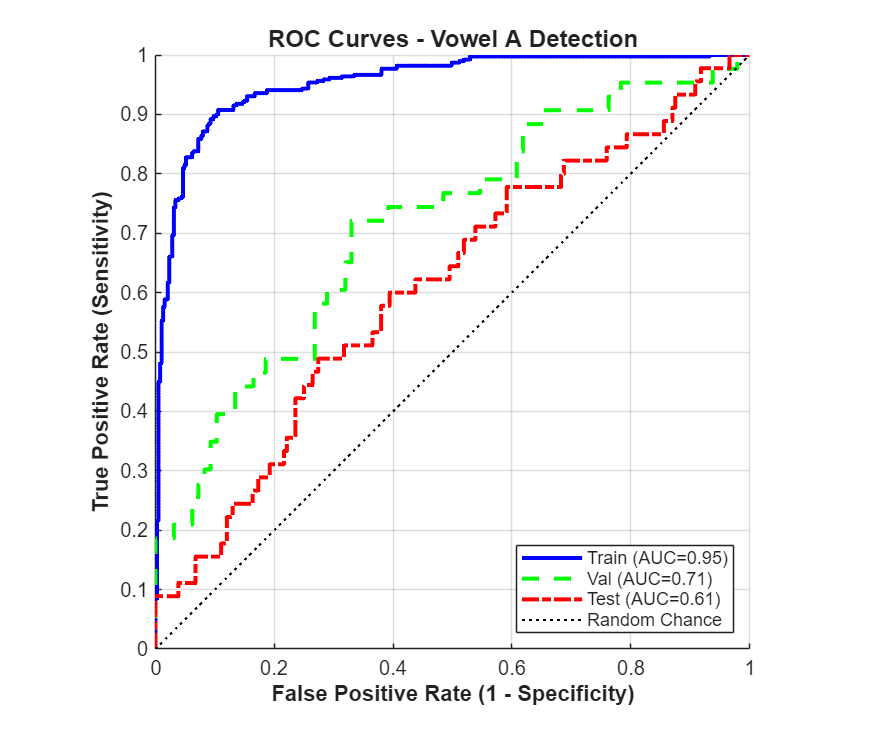


% 3. PLOT ROC CURVES
figure('Name', 'ROC Curves', 'Color', 'w', 'Position', [100 100 600 500]);
hold on;

% Plot lines
plot(Xroc_train, Yroc_train, 'LineWidth', 2, 'Color', 'b', 'DisplayName', sprintf('Train (AUC=%.2f)', AUC_train));
plot(Xroc_val,   Yroc_val,   'LineWidth', 2, 'Color', 'g', 'LineStyle', '--', 'DisplayName', sprintf('Val (AUC=%.2f)', AUC_val));
plot(Xroc_test,  Yroc_test,  'LineWidth', 2, 'Color', 'r', 'LineStyle', '-.', 'DisplayName', sprintf('Test (AUC=%.2f)', AUC_test));

% Plot diagonal "Random Chance" line
plot([0 1], [0 1], 'k:', 'LineWidth', 1, 'DisplayName', 'Random Chance');

% Formatting
xlabel('False Positive Rate (1 - Specificity)', 'FontWeight', 'bold');
ylabel('True Positive Rate (Sensitivity)', 'FontWeight', 'bold');
title('ROC Curves - Vowel A Detection', 'FontSize', 12);
legend('Location', 'SouthEast');
grid on;
axis square; % Makes the plot square-shaped
hold off;


fprintf(' ROC Curves plotted successfully.\n\n');

 ROC Curves plotted successfully.




%% BLOCK 16: FINAL SUMMARY
fprintf('╔════════════════════════════════════════════╗\n');

╔════════════════════════════════════════════╗


fprintf('║  TRAINING COMPLETE                         ║\n');

║  TRAINING COMPLETE                         ║


fprintf('╠════════════════════════════════════════════╣\n');

╠════════════════════════════════════════════╣


fprintf('║  Total time: %.1f minutes                  ║\n', trainTime/60);

║  Total time: 4.1 minutes                  ║


fprintf('║  Test accuracy: %.2f%%                     ║\n', acc_test*100);

║  Test accuracy: 64.82%                     ║


fprintf('║  Test F1-Score: %.2f%%                     ║\n', F1_test*100);

║  Test F1-Score: 33.08%                     ║


fprintf('╚════════════════════════════════════════════╝\n');

╚════════════════════════════════════════════╝


fprintf('\n All done!\n');


 All done!


%% HELPER FUNCTION (MUST BE AT END!)
function features = extractLSTMFeatures(table, idx, freqMin, freqMax, sampleRate)
    
    % Spectrogram
    spec1 = abs(single(table.EMG_ch1_Spectrogram{idx}));
    spec2 = abs(single(table.EMG_ch2_Spectrogram{idx}));

    
    freqsSpec = linspace(0, sampleRate/2, size(spec1,1));
    freqIdxSpec = (freqsSpec >= freqMin) & (freqsSpec <= freqMax);
    spec1_filtered = spec1(freqIdxSpec, :);
    spec2_filtered = spec2(freqIdxSpec, :);

    currentWidth = size(spec1_filtered, 2);
    
    % Align time
    %minTimeSteps = min([nTimeSamples, size(cwt1_filtered,2), size(spec1_filtered,2)]);
    spec1_resized = imresize(spec1_filtered, [450, currentWidth]);
    spec2_resized = imresize(spec2_filtered, [450, currentWidth]);
    
    % Stack features
    features = [spec1_resized; spec2_resized];
    features = single(features);
end

